# Desarrollo Laboratorio 3 - Robótica 2021-II

### Edgar Alejandro Ruíz Velasco

### Jesus Daniel Caballero Colina

### Jhohan David Contreras Aragón

**Para este equipo de trabajo se asignó el robot industrial *****Epson C4***

### Parte 1 Ruta:

El presente equipo de trabajo es el no. 6, por ende el plano vector asignado es $\left\lbrack 0,1,1\right\rbrack$. Además se seleccionó la ruta:

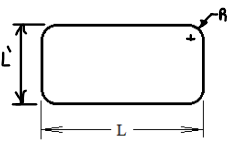

Donde L corresponde a 0.4 del alcance horizontal máximo del robot. Según el manual del robot C4 (investigación realizada en taller 1) el alcance horizontal máximo es de 665 mm, es decir que $L=0\ldotp 4\;\left(665\mathrm{mm}\right)=266\mathrm{mm}$. La otra dimensión del rectangulo se va a tomar como $L^{\prime } =0\ldotp 5L=133\mathrm{mm}$ y el radio de cada esquina se va a tomar como $R=20\mathrm{mm}$. Por último, el centro del rectangulo de la pista se posicionó $\left\lbrack x,y,z\right\rbrack =\left\lbrack 0,415,570\right\rbrack$ (posición de calibración del robot).

Ahora se hallan los puntos de la ruta, siguiendo las dimensiones delimitadas anteriormente, en el plano XY y centrado en la posición de calibración del robot:

% Dimensiones y posición de ruta
P_centro = [0,415,570];
L = 266;
L1 = 133;
R = 20;
% Especificación de ruta
n = 200; %Número de viapoints

%--------------------------------------------
Perimetro = (L-2*R)*2 + (L1-2*R)*2 + 2*pi*R;
d = Perimetro / n; % Distancia entre puntos

viapoints = zeros(n,3);
% El primero punto se escoge en la posición superior central del rectangulo
i = 1;
x = 0;
while (x < L/2-R)
    viapoints(i,1:3) = [x,L1/2,0]+P_centro;
    x = x + d;
    i = i + 1;
end
d1 = x - (L/2-R);
theta1 = d1/R;
theta2 = d/R;

theta = theta1;
while theta < pi/2
    viapoints(i,1:3) = [sin(theta),cos(theta),0]*R+[L/2-R,L1/2-R,0]+P_centro;
    theta = theta + theta2;
    i = i + 1;
end
d1 = (theta2-(theta-pi/2))*R;
d2 = d - d1;

y = L1/2 - R - d2;
while y > R - L1/2
    viapoints(i,1:3) = [L/2,y,0]+P_centro;
    y = y - d;
    i = i + 1;
end
d1 = (R - L1/2) - y;
theta1 = d1/R;
theta2 = d/R;

theta = pi/2 + theta1;
while theta < pi
    viapoints(i,1:3) = [sin(theta),cos(theta),0]*R+[L/2-R,-L1/2+R,0]+P_centro;
    theta = theta + theta2;
    i = i + 1;
end
d1 = (theta2-(theta-pi))*R;
d2 = d - d1;

x = L/2 - R - d2;
while x > R - L/2
    viapoints(i,1:3) = [x,-L1/2,0]+P_centro;
    x = x - d;
    i = i + 1;
end
d1 = (R - L/2) - x;
theta1 = d1/R;
theta2 = d/R;

theta = pi + theta1;
while theta < 3*pi/2
    viapoints(i,1:3) = [sin(theta),cos(theta),0]*R+[-L/2+R,-L1/2+R,0]+P_centro;
    theta = theta + theta2;
    i = i + 1;
end
d1 = (theta2-(theta-3*pi/2))*R;
d2 = d - d1;

y = - L1/2 + R + d2;
while y < L1/2 - R
    viapoints(i,1:3) = [-L/2,y,0]+P_centro;
    y = y + d;
    i = i + 1;
end
d1 = y - (L1/2 - R);
theta1 = d1/R;
theta2 = d/R;

theta = 3*pi/2 + theta1;
while theta < 2*pi
    viapoints(i,1:3) = [sin(theta),cos(theta),0]*R+[-L/2+R,L1/2-R,0]+P_centro;
    theta = theta + theta2;
    i = i + 1;
end
d1 = (theta2-(theta-2*pi))*R;
d2 = d - d1;

x = -L/2 + R + d2;
while x < 0
    viapoints(i,1:3) = [x,L1/2,0]+P_centro;
    x = x + d;
    i = i + 1;
end

close all
figure("Name","Ruta")
hold on
for j = 1:n
   plot3(viapoints(j,1),viapoints(j,2),viapoints(j,3),'b.','MarkerSize',10);
end
xlim([-133 133])
ylim([348 482])

Teniendo los puntos en el plano XY se procede a rotar cada uno de tal manera que queden en el plano vector $\left\lbrack 0,1,1\right\rbrack$.

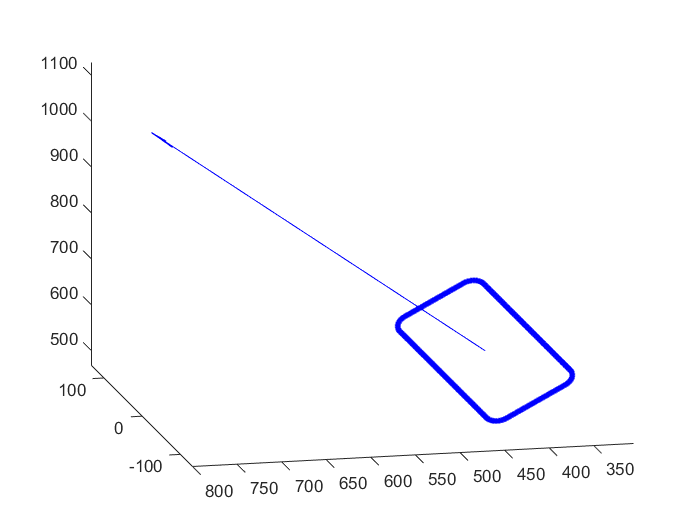

MTH = rotx(-pi/4);
for i = 1:n
    viapoints(i,1:3) = (MTH*(viapoints(i,1:3)-P_centro)')'+P_centro;
end

close all
figure("Name","Ruta")
hold on
for j = 1:n
   plot3(viapoints(j,1),viapoints(j,2),viapoints(j,3),'b.','MarkerSize',10);
end
quiver3(P_centro(1),P_centro(2),P_centro(3),P_centro(1),P_centro(2)+1,P_centro(3)+1,'blue')

xlim([-133 133])
ylim([305 800])
zlim([467 1127])
view([-103 19])